# OFDM Transmitter and Receiver

`Source: https://es.mathworks.com/help/comm/ug/ofdm-transmitter-and-receiver.html#OFDMEndToEndExample-1`

This example shows how to run a complete end-to-end OFDM transmission system for a single-input single-output (SISO) channel. The physical-layer transmission protocol mimics typical synchronization signals, reference symbols, control channels, and data channels popular across standardized transmission schemes such as LTE, 5G NR, and WLAN. The example can be used to test different transmission signals and receiver algorithms across various channels and radio impairments. This processing includes scrambling, convolutional encoding, modulation, filtering, channel distortion, demodulation, maximum likelihood decoding, and more.

The transmitter models control channels and data channels in this example. Transmitted data bits are split into transport blocks and OFDM-modulated. Control signals are multiplexed in with the data signals for synchronization, signaling, and estimation of impairments. Channel impairments distort the transmitted signal in the time domain. The impairments include multipath fading and noise, and carrier frequency offset is modeled as a receiver impairment. The receiver models sample buffering for timing adjustment, filtering, carrier frequency adjustment, and OFDM demodulation and decoding.

The example allows exploration of different system parameters, channel impairments, and receiver operations through editor controls. Visualization aids are also enabled or disabled through editor controls to see the effects of the different combinations of parameters, impairments, and receiver algorithms.

## System Parameters

Select the system parameters from a set of allowed values. These parameters are transmitted within the frame header and decoded by the receiver. The entries are representative of typical LTE, WLAN, and 5G NR transmission parameters. More entries may be added as desired, taking note that most parameters have interdependencies on other parameters.

BWIndex = {FFT length, CP length, number of occupied subcarriers, subcarrier spacing, pilot subcarrier spacing, channel BW}:

- 1 = {128, 32, 72, 15e3, 9, 1.4e6}

- 2 = {256, 64, 180, 15e3, 20, 3e6}

- 3 = {512, 128, 300, 15e3, 20, 5e6}

- 4 = {1024, 256, 600, 15e3, 20, 10e6} (default)

- 5 = {2048, 512, 1200, 15e3, 24, 20e6}

- 6 = {128, 32, 112, 312.5e3, 14, 35.6e6}

- 7 = {4096, 1024, 3276, 30e3, 36, 98.28e6}

Modulation order for all data subcarriers:

- 2 = BPSK

- 4 = QPSK

- 16 = 16-QAM

- 64 = 64-QAM (default)

- 256 = 256-QAM

- 1024 = 1024-QAM

Code rate:

- 0 = 1/2 (default)

- 1 = 2/3

- 2 = 3/4

- 3 = 5/6

Several controls are available to enable or disable receiver impairments and scopes for transceiver visualization. It is recommended that visualizations be disabled for long simulations and/or simulations over multiple SNRs. Controls are also available to enable or disable certain receiver algorithms.

Change the output verbosity to control the diagnostic output text. The "`Low`" setting suppresses diagnostic output during frame processing. The "`High`" setting enables all output.

% Clear persistent state variables and buffers, and close all figures
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMChannel helperOFDMFrequencyOffset
close all;
clear all;
aux = false;
aux_fft = false;
i_sa = 1;


userParam = struct( ...
    'BWIndex',          2, ...   % Index corresponding to desired bandwidth
    'modOrder',         2, ...   % Subcarrier constellation modulation order
    'codeRateIndex',    3, ...   % Code rate index corresponding to desired rate
    'numSymPerFrame',   12, ...   % Number of OFDM symbols per frame
    'numFrames',        100, ...   % Number of frames to be generated for simulation (12-500)
    'fc',               5.9, ...   % Carrier frequency (GHz)
    'chanVisual',       "All", ...   % Channel fading visualization option
    'enableCFO',        false                 , ...   % Enable/disable carrier frequency offset compensation
    'enableCPE',        true                 , ...   % Enable/disable common phase error compensation
    'enableScopes',     true                 , ...   % Enable/disable scopes
    'enablePFO',        false                 , ...   % Enable Phase-frequency offset
    'verbosity',        0, ...
    'print_allData',    true                 );    % Print both the Equalized Data and the no equalized Data

    % Diagnostic output verbosity

userParam.fc = userParam.fc*10^9;
lambda = physconst('LightSpeed')/userParam.fc;

## Channel Model Selection 

The suported Channel Models were defined in two different documents: 

- The CDL-x channel models are extracted from the "*Study on channel model for frequencies from 0.5 to 100 GHz*" document from the 3GPP TR 38.901 v.17.0.0

- The Urban_x and Highway_x channel models are extracted from the "*Study on evaluation methodology of new Vehicle-to-Everything (V2X) use cases for LTE and NR*" document from the 3GPP TR 37.885 v.15.3.0

The used channel models have been clasified in terms of the existance of Line of Sight, in other words, in terms of the vision between the transmiter and the receiver. 

- No Line Of Sight --> 'CDL-A', 'CDL-B', 'CDL-C', 'Urban_NLOS_V2X'

- Line of Sight --> 'CDL-D', 'CDL-E', 'Urban_LOS_V2X', 'Highway_LOS_V2X'

- Vehicular No Line Of Sight --> Urban_vNLOS_V2X, 'Highway_vNLOS_V2X'

The vehicular channel models are only defined for a carrier frequency of 5.9Ghz, this is because the document states that. 

**ONLY fc = 5.9GHz for 'Urban_LOS_V2X', 'Urban_NLOS_V2X', 'Urban_vNLOS_V2X', 'Highway_LOS_V2X', 'Highway_vNLOS_V2X'**

The supported scenarios **only** for the CDL-x channel models 

- Urban Micro --> 'UMI' 

- Urban Macro --> 'UMA'

- Rural Macro --> 'RMA' (2-6GHz)

This scenarios scale the normalized delays of the original CDL-x models, in other to adapt these models to the selected scenario. The model is scaled by the desired RMS delay spread in seconds as stated in TR 38.901 Section 7.7.3

**The scenario isn't suported in the vehicular models Urban_x and Highway_x.**

channelModelParam = struct('model', 'CDL-C', ... % Channel Model        
    'scenario', 'UMI');  % Scenario 

## Antenna Settings

antennaParam = struct('antennaSystem',"estRefsignals",... % Reference Signal Estimation or ofdmChannelResponse Estimation
    'TransmitArrayOrientation', [0; 0; 0],... %  [α; β; γ]. The vector elements specify the bearing, downtilt, and slant rotation angles in degrees.
    'ReceiveArrayOrientation', [0; 0; 0],... %  [α; β; γ]. The vector elements specify the bearing, downtilt, and slant rotation angles in degrees.
    'AntennasAligned',false); % If pressed Tx and Rx antennas are aligned

## Antenna Array Tx

If the antenna Tx is a Struct

antennaTxStruct = struct('ElementSpacing',[0.5 0.5 1.0 1.0] ,... %IN WAVELENGTHS
    'PolarizationAngles',[45 -45], ... %
    'Element',"38.901", ...
    'PolarizationModel',"Model-2");
antennaTx = antennaTxStruct;

% Element spacing, in WAVELENGTHS, specified as a row vector of the form [λv λh dgv dgh]. 
% The vector elements represent the vertical and horizontal element spacing and the vertical and horizontal panel spacing,
% respectively. The panel spacing is measured from the center of the panels.

% Polarization angles in degrees, specified as a row vector of the form [θ ρ].

## Antenna Array Rx

If the antenna Rx is a Struct

antennaRxStruct = struct('ElementSpacing',[0.5 0.5 0.5 0.5] ,... %IN WAVELENGTHS
    'PolarizationAngles',[0 90], ...
    'Element',"isotropic", ...
    'PolarizationModel',"Model-2");
antennaRx = antennaRxStruct;

% Element spacing, in WAVELENGTHS, specified as a row vector of the form [λv λh dgv dgh]. 
% The vector elements represent the vertical and horizontal element spacing and the vertical and horizontal panel spacing,
% respectively. The panel spacing is measured from the center of the panels.

% Polarization angles in degrees, specified as a row vector of the form [θ ρ].

## Mobile Environment and Impairments

The velocity inversely affects the channel coherence time (specifically, the amount of time the channel distortion is roughly constant). Since the beginning of each frame contains a reference signal to measure the channel distortion, set the velocity so that the coherence time is sufficiently greater than the frame period (controlled by the number of symbols per frame). To select a velocity, consider a generally accepted estimate of the coherence time $T_c=c/(v*f)$, where $c$ is the speed of light, $v$ is the velocity, and $f$ is the carrier frequency.

The frequency offset is the difference between the transmitter and receiver at the baseband frequency. This parameter is commonly expressed in parts per million (ppm). For example, a 100 Hz offset with respect to a sampling frequency of 30.72 MHz yields an offset of 3.25 ppm.

Multipath fading causes nulls in some parts of the transmitted spectrum; interleaving helps to spread user data across all frequencies, so that some of the redundant bits are received on unaffected subcarriers. Decreasing the coding rate in the system parameters also helps to generate more redundant bits and increase the chances of error correction, but at the cost of lower user data throughput.

User Element speed in km/h, values for each scenario:

- Urban Micro --> 0 - 30km/h    

- Urban Macro --> 0 - 30km/h 

- Rural Macro --> 60 - 120 km/h 

Guidelines for evaluation of radio interface technologies for IMT-2020

There are two options for the simulation, the first one is specify the impairments and the desired signal-to-noise ratio (SNR) assuming no channel loss or fading. Specify the SNR as a scalar value or create a vector of SNR values to run multiple simulations at different SNRs, and then create a BER plot. Note that sync symbol detection at low SNRs may not be possible. The other option is availabvle is the definition of the SNR based on the distance between the UE and the BS. In the next part "Tx and Rx Site Configuration" all the information is explained.

This is controlled by sim_SNR_used.

If endSimBER0 is ticked the simulations ends if the BER is 0

sim_SNR_used = "SNR_manual"; % Whether to use a list of SNR values or SNR obtained by distance between Tx and Rx
endSimBER0 = false; % If ticked, ends the simulation if the BER is 0
%If sim_SNR_used = SNR_manual this is the SNR used
SNRdB = 1:1:30; 
v_ue  = 30; % mobile velocity (km/h)
% UT Angles of Travel Direction
angulo_azimuth = 0; %Azimuth Angle --> azimuth 0º (x axix) | azimuth 90º (y axix)
angulo_zenith  = 0; %Zenith Angle --> zenith 0º (z axix) | zenith 90º (y axix)
foff  = 0; % frequency offset (ppm)

BERResults = zeros(size(SNRdB));

% Mobility Struct
mobilityParam = struct('v_ue',v_ue,'angulo_azimuth',angulo_azimuth,'angulo_zenith',angulo_zenith);

**CDL Channel Models Object**

https://es.mathworks.com/help/5g/ref/nrcdlchannel-system-object.html#mw_a9218ea8-ec70-4fe8-8622-9c62f5649a9c

Escenario Urban Micro NLOS


cdl_channelModel =   nrCDLChannel with properties:

                 DelayProfile: 'CDL-C'
                 AngleScaling: false
                  DelaySpread: 9.3041e-08
             CarrierFrequency: 5.9000e+09
          MaximumDopplerShift: 164.0023
          UTDirectionOfTravel: [2×1 double]
                   SampleRate: 30720000
         TransmitAntennaArray: [1×1 struct]
     TransmitArrayOrientation: [3×1 double]
          ReceiveAntennaArray: [1×1 struct]
      ReceiveArrayOrientation: [3×1 double]
           NormalizePathGains: true
                SampleDensity: 64
                  InitialTime: 0
                 RandomStream: 'mt19937ar with seed'
                         Seed: 73
      NormalizeChannelOutputs: true
             ChannelFiltering: true
    TransmitAndReceiveSwapped: false


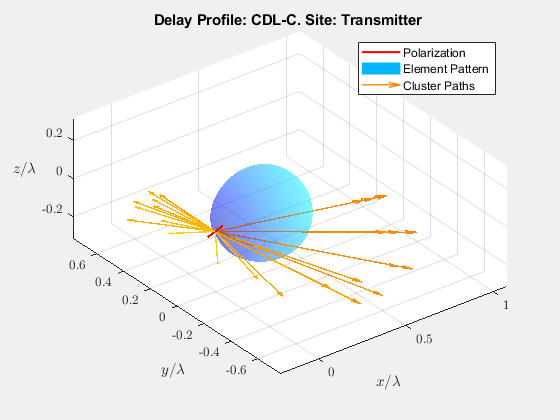

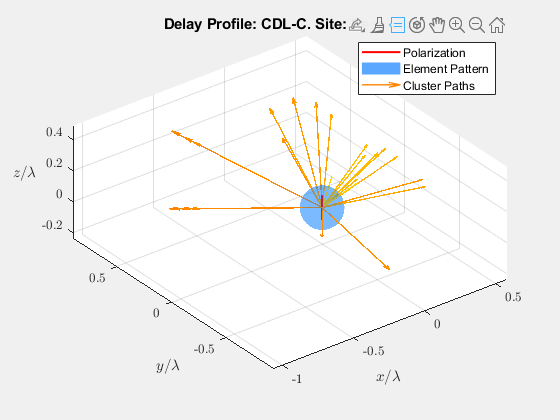

[cdl_channelModel] = helperChannelSelection(channelModelParam,antennaParam,userParam,mobilityParam,antennaTx,antennaRx);

[sysParam, txParam] = helperOFDMSetParameters(userParam,antennaParam);

## Tx and Rx Site Configuration

Select the characteristics of the transmiter and receiver elements.

Source: [https://es.mathworks.com/help/5g/ug/include-path-loss-in-nr-link-level-simulations.html](https://es.mathworks.com/help/5g/ug/include-path-loss-in-nr-link-level-simulations.html)

Recommendations in Study on evaluation methodology of new Vehicle-to-Everything (V2X) use cases for LTE and NR;

- Power Base Station 

- UE and BS Receiver Noise Figure 

- UE Antenna Height values

- Type 1 (passenger vehicle with lower antenna position): antenna height 0.75 meters

- Type 2 (passenger vehicle with higher antenna position): antenna height 1.6 meters

- Type 3 (truck/bus):  antenna height 3 meters.

- BS Antenna Height values

ISD = Inter-BS distance

**Road Configuration for Urban Grid**

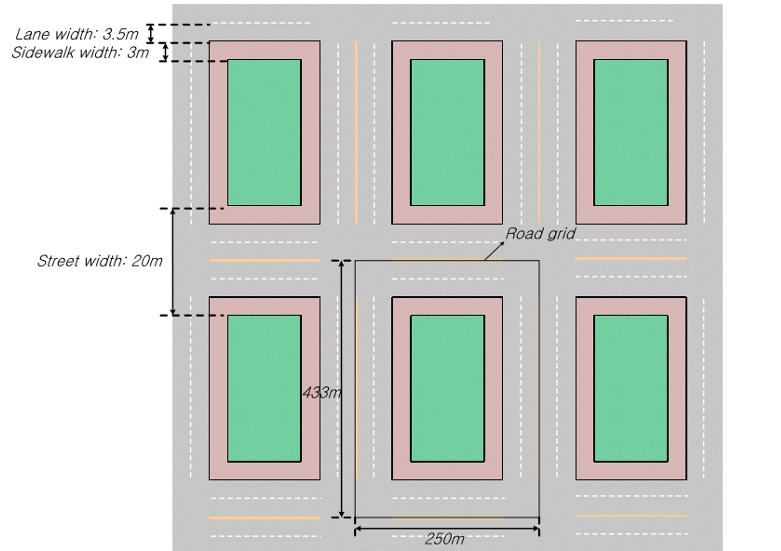

**Road Configuration For Highway Scenario**

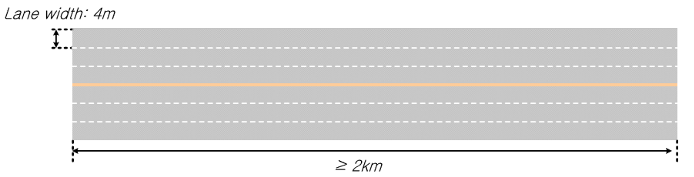

if (strcmp(sim_SNR_used,"SNR_by_distance")) == true
    %If sim_SNR_used = SNR_by_distance this is the parameters used for the SNR calculation
    pathLossParam.TxHeight = 5;             % Height of the BS antenna (m)
    pathLossParam.TxPower = 24;              % Power delivered to all antennas of the BS on a fully allocated grid (dBm)

    pathLossParam.RxHeight = 0.75;             % Height of UE antenna (m)
    pathLossParam.RxNoiseFigure = 9;        % Noise figure of the UE (dB)
    pathLossParam.RxAntTemperature = 290;     % Antenna temperature of the UE (K)
    pathLossParam.TxRxDistance = 1:100:201;   % Distance between the BS and UE (m)

    % Enviroment Settings
    pathLossParam.BuildingHeight = 5;     % Height of the Buildings (m)
    pathLossParam.EnvironmentHeight = 1;  % Height of the Environment (m)
    pathLossParam.StreetWidth = 30;        % Street Width (m)


## Configure Propagation Channel

The propagation channel model includes path loss and small-scale fading. The path loss depends on the distance between the BS and UE, the carrier frequency, and other parameters that are specific to each scenario. In the fading channels clustered delay line (CDL) the fading channel configuration determines the line-of-sight (LOS) existence between the transmitter (BS) and receiver (UE), which is required for path loss calculation. Delay profiles A, B, and C configure non-LOS channels and delay profiles D and E configure LOS channels. In the case of vehicular models, the model LOS is included in the name of the model.

### Configure Path Loss

Configure the scenario and other path loss parameters of the 5G path loss model as defined in TR 38.901 Section 7.4. Alternatively, specify the free-space path loss model. The path loss model determines the average attenuation of the transmitted signal.

    pathLossParam.PathLossModel = "5G-NR"; % 5G path loss model as defined in TR 38.901 Section 7.4. 
                                                        % Or free-space path loss model
    pathLossParam.PathLoss = nrPathLossConfig;
    pathLossParam.PathLoss.Scenario = channelModelParam.scenario; 
    pathLossParam.PathLoss.EnvironmentHeight = pathLossParam.EnvironmentHeight;


Transmitting at 5900 MHz with an occupied bandwidth of 2.700000e+00 MHz


    pathLossParam.PathLoss.BuildingHeight = pathLossParam.BuildingHeight;
    pathLossParam.PathLoss.StreetWidth = pathLossParam.StreetWidth;   

### Configure Fading Channel and LOS

    chInfo = info(cdl_channelModel);
    kFactor = chInfo.KFactorFirstCluster; % dB
    
    % Determine LOS between Tx and Rx based on Rician factor K.
    pathLossParam.LOS = kFactor>-Inf;

## Calculate Propagation Path Loss

    if (strcmp(channelModelParam.model,'Urban_LOS_V2X') || strcmp(channelModelParam.model,'Urban_NLOS_V2X') || strcmp(channelModelParam.model,'Urban_vNLOS_V2X') || strcmp(channelModelParam.model,'Highway_LOS_V2X') || strcmp(channelModelParam.model,'Highway_vNLOS_V2X')) == true
        userParam.fc = 5.910^9;        
    end
    
    % Calculate the path loss.
    if strcmp(pathLossParam.PathLossModel,'5G-NR') == true
        txPosition = [0;0; pathLossParam.TxHeight];
        dtr = pathLossParam.TxRxDistance;
        rxPosition = [dtr; zeros(size(dtr)); pathLossParam.RxHeight*ones(size(dtr))];
        pathLoss = nrPathLoss(pathLossParam.PathLoss,userParam.fc,pathLossParam.LOS,txPosition,rxPosition);
    else % Free-space path loss
        lambda = physconst('LightSpeed')/userParam.fc;
        pathLoss = fspl(userParam.TxRxDistance,lambda);
    end


## Calculate Antenna and Receiver Noise

This section calculates the equivalent noise temperature and amplitude per receive antenna element from the input noise temperature and receiver internal noise. The noise amplitude per receive antenna is


$$N_{0\;} =\sqrt{\frac{1}{2}k\;B\;T_{\mathrm{e}} }$$


where $k$ is the Boltzmann constant ($1\ldotp 3807\times {10}^{-23} \;{\textrm{JK}}^{-1}$). $B$ is the bandwidth, which is equal the waveform sample rate. The equivalent noise temperature $T_{\mathrm{e}}$ is

$T_{\mathrm{e}} =T_{\mathrm{Ant}} +290\cdot \left(NF-1\right)$,

$T_{\textrm{Ant}}$ is the input noise temperature and $\textrm{NF}$ is the receiver noise figure in linear units.

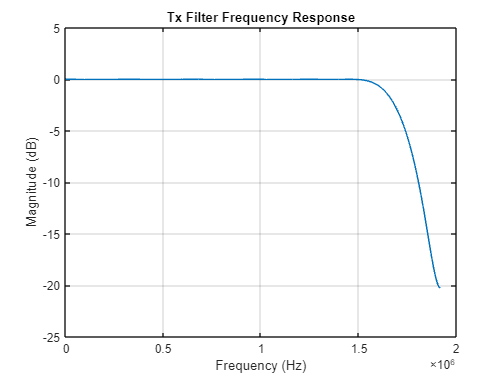

    kBoltz = physconst('Boltzmann');

    NF = 10^(pathLossParam.RxNoiseFigure/10);
    Teq = pathLossParam.RxAntTemperature + 290*(NF-1); % K
    sampleRate = sysParam.scs * sysParam.FFTLen;
    N0 = sqrt(kBoltz*sampleRate*Teq/2.0);

Configuring the fading AWGN channel at 1 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 2 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 3 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 4 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 5 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 6 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 7 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 8 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 9 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 10 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 11 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 12 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 13 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 14 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 15 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 16 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 17 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 18 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 19 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 20 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 21 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 22 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 23 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 24 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 25 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 26 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 27 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 28 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 29 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

Configuring the fading AWGN channel at 30 dB SNR and 30 kph...


Transmitting 100 frames with transport block size of 1242 bits per frame...


Searching for synchronization symbol...

## Calculate Signal-to-Noise Ratio (SNR)

This section uses the configuration parameters to calculate the SNR per resource element (RE) resulting from the transmit power, receive noise, bandwidth, and path loss. The average receive signal per RE and the receive antenna and noise power per RE are

$S\equiv P_{\mathrm{RE}}^S =\frac{P_{\mathrm{Tx}} }{L}\cdot \frac{N_{\mathrm{FFT}}^2 }{{12N}_{\mathrm{grid}}^{\mathrm{size}} }$ and

$N\equiv \;P_{\textrm{RE}}^N =2N_0^2 {\;N}_{\textrm{FFT}}$.

$P_{\textrm{Tx}}$ is the total transmitted power at the transmit antenna array input. $N_{\textrm{FFT}}$ is the number of fast Fourier transform (FFT) points used for OFDM modulation. $N_{\textrm{grid}}^{\textrm{size}}$ is the size of the OFDM grid in resource blocks. $L$ is the path loss. ${\sqrt{\;2}N}_0$ is root-mean-square (RMS) value of the noise per receive antenna. The average SNR per RE and receive antenna is

${\left(\frac{S}{N}\right)}_{\textrm{dB}} =10\log_{10} \left(P_{\textrm{Tx}} \right)-10\log_{10} \left(L\right)+10\log_{10} \left(\frac{N_{\textrm{FFT}} }{{12N}_{\textrm{grid}}^{\textrm{size}} }\right)-10\log_{10} \left(2N_0^2 \right)$.

    %Number of RBs = (Subcarriers per RB/Number of occupied subcarriers) × numSymPerFrame
    NSizeGrid = (sysParam.FFTLen/sysParam.usedSubCarr)* sysParam.numSymPerFrame; % Bandwidth in number of resource blocks

    fftOccupancy = 12*NSizeGrid/sysParam.FFTLen;
    sysParam.SNRIn = (pathLossParam.TxPower-30) - pathLoss - 10*log10(fftOccupancy) - 10*log10(2*N0^2);

    SNRInc = mat2cell(sysParam.SNRIn(:),length(pathLoss),1);
    tSNRIn = table(pathLossParam.TxRxDistance(:),SNRInc{:},'VariableNames',{'Distance Tx-Rx (m)','SNR (dB)'});
    disp(tSNRIn)
    SNRdB = sysParam.SNRIn;
    BERResults = zeros(size(SNRdB));
    plot(pathLossParam.TxRxDistance,SNRdB)
end

## Populate Parameter Structure

The helper function `helperOFDMSetParameters` configures the system parameters common to the transmitter and receiver.

Coding parameters specify the channel coding parameters that are applied to the data payload for scrambling, interleaving, and convolutional encoding purposes. These parameters are shared between the transmitter and receiver. The system uses a 7th-degree scrambler polynomial, interleaving depth of 12 for header data and 18 for payload data, a base convolutional coding rate of 1/2, and a 32-bit CRC.

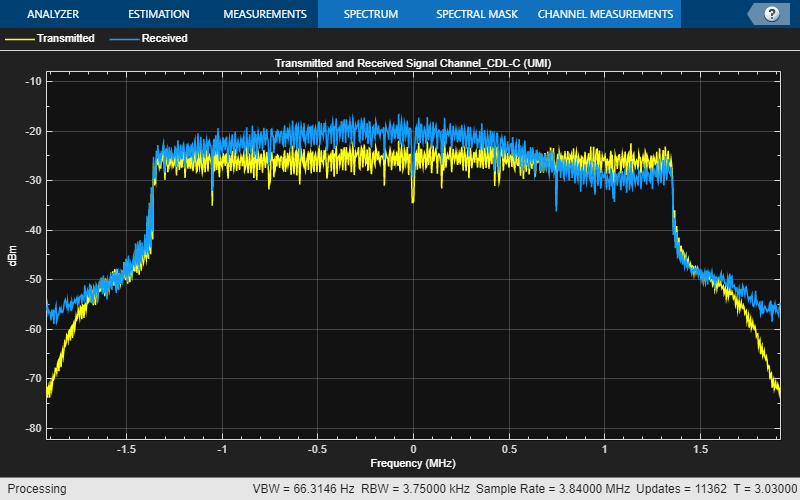

%[sysParam, txParam] = helperOFDMSetParameters(userParam,antennaParam);

[~,codeParam] = helperOFDMGetTables(userParam.BWIndex,userParam.codeRateIndex);
codeRate = codeParam.codeRate; % Coding rate

fprintf('\nTransmitting at %d MHz with an occupied bandwidth of %d MHz\n', ...
    sysParam.fc/1e6,sysParam.scs*sysParam.usedSubCarr/1e6);
% Calculate fading channel impairments
KPH_TO_MPS = (1000/3600);
fsamp = sysParam.scs*sysParam.FFTLen;       % sample rate of signal
T = (sysParam.FFTLen+sysParam.CPLen)/fsamp; % symbol duration (s)
fmax = v_ue * KPH_TO_MPS * sysParam.fc / physconst('LightSpeed');  % Maximum Doppler shift of diffuse components (Hz)

% Set up scopes
if userParam.enableScopes
    % Set up constellation diagram object
    refConstHeader = qammod(0:1,2,UnitAveragePower=true); % header is always BPSK
    refConstData   = qammod(0:txParam.modOrder-1,txParam.modOrder,UnitAveragePower=true);
    
    if userParam.print_allData == 0
        constDiag = comm.ConstellationDiagram(2, ...
        "ChannelNames",{'Header','Data'}, ...
        "ReferenceConstellation",{refConstHeader,refConstData}, ...
        "ShowLegend",true, ...
        "EnableMeasurements",true,...
        "Name","Constellation Diagram of the Received Data");
    else
         constDiag = comm.ConstellationDiagram(2, ...
        "ChannelNames",{'Header','Data'}, ...
        "ReferenceConstellation",{refConstHeader,refConstData}, ...
        "ShowLegend",true, ...
        "EnableMeasurements",true, ...
        "Name","Constellation Diagram of the Received Data");



Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................


Sync symbol found.
Receiver camped.
...............................................................................
.....................

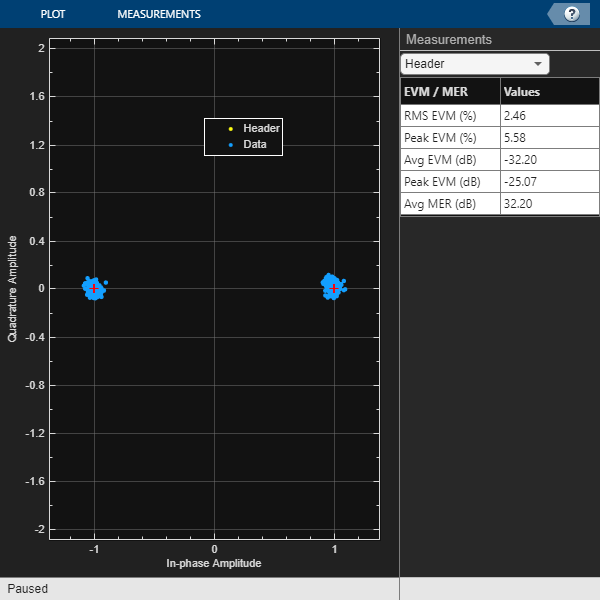

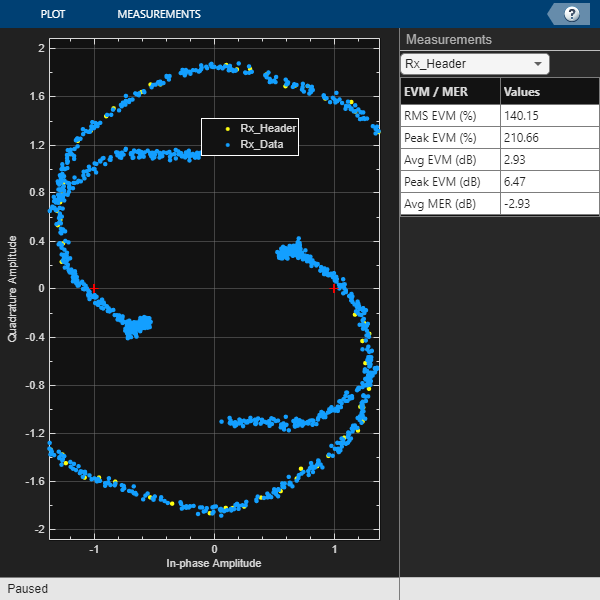

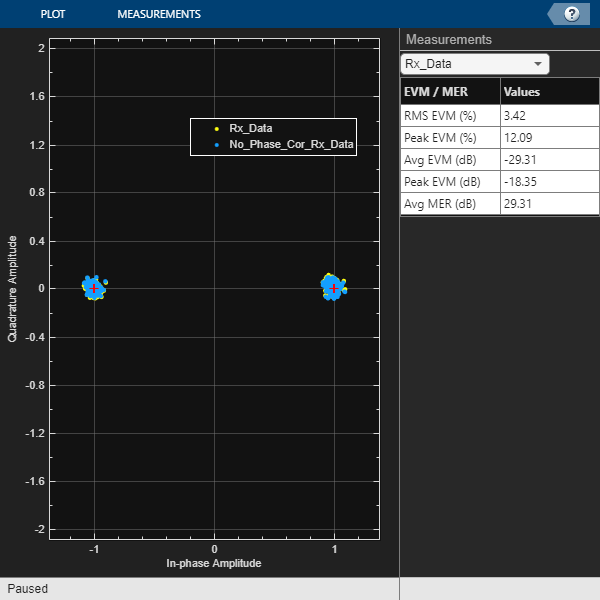

         constDiag_noEq = comm.ConstellationDiagram(2, ...
        "ChannelNames",{'Rx_Header','Rx_Data'}, ...
        "ReferenceConstellation",{refConstHeader,refConstData}, ...
        "ShowLegend",true, ...
        "EnableMeasurements",true,...
        "Name","Constellation Diagram No Demodulated Data");
        
         constDiag_phase = comm.ConstellationDiagram(2, ...
        "ChannelNames",{'Rx_Data','No_Phase_Cor_Rx_Data'}, ...
        "ReferenceConstellation",{refConstData,refConstData}, ...
        "ShowLegend",true, ...
        "EnableMeasurements",true,...
        "Name","Constellation Diagram Effect No Phase Correction");

    end
    channelName = cell(1, 2);
    channelName{1} = ['Transmitted'];
    channelName{2} = ['Received'];
    % Set up spectrum analyzer visualization object

    name = strcat(strcat(strcat(strcat('Transmitted and Received Signal Channel_',channelModelParam.model),' ('),channelModelParam.scenario),')');
    sa = spectrumAnalyzer( ...
        'Name',             'Signal Spectra', ...
        'Title',            name, ...
        'SpectrumType',     'Power', ...
        'FrequencySpan',    'Full', ...
        'SampleRate',       fsamp, ...
        'ShowLegend',       true, ...
        'Position',         [100 600 800 500], ...
        'ChannelNames',     channelName);

end

## Initialize States and Process Data Frames

For each SNR specified in the user settings, the receiver begins in an unsynchronized, unassociated, and unconnected state. The receiver must detect the start of a frame through sync symbol detection and synchronize the receive sample buffers to begin storing samples when the beginning of the transmit frame is received. The receiver must then estimate the frequency offset and align its internal clock to match the transmitter clock; it is then considered "camped" (associated) with the base station. Finally, after header information is received and decoded, the receiver transitions to a connected state and begins decoding data.

Once connected, the simulation loops though the frame processing to generate a transmit frame, distort the output samples through a channel filter, and process the received samples to produce the transport block bitstream.

% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);
% Initialize receiver
rxObj = helperOFDMRxInit(sysParam);

Simulation completed at 1.00 SNR: BER = 2.335749e-02, FER = 4.400000e-01


Simulation completed at 2.00 SNR: BER = 7.431562e-03, FER = 2.800000e-01


Simulation completed at 3.00 SNR: BER = 1.819646e-03, FER = 8.000000e-02


Simulation completed at 4.00 SNR: BER = 2.238325e-03, FER = 7.000000e-02


Simulation completed at 5.00 SNR: BER = 0, FER = 1.000000e-02


Simulation completed at 6.00 SNR: BER = 0, FER = 0


Simulation completed at 7.00 SNR: BER = 1.529791e-04, FER = 2.000000e-02


Simulation completed at 8.00 SNR: BER = 0, FER = 0


Simulation completed at 9.00 SNR: BER = 0, FER = 0


Simulation completed at 10.00 SNR: BER = 0, FER = 0


Simulation completed at 11.00 SNR: BER = 0, FER = 0


Simulation completed at 12.00 SNR: BER = 0, FER = 0


Simulation completed at 13.00 SNR: BER = 0, FER = 0


Simulation completed at 14.00 SNR: BER = 0, FER = 0


Simulation completed at 15.00 SNR: BER = 0, FER = 0


Simulation completed at 16.00 SNR: BER = 0, FER = 0


Simulation completed at 17.00 SNR: BER = 0, FER = 0


Simulation completed at 18.00 SNR: BER = 0, FER = 0


Simulation completed at 19.00 SNR: BER = 0, FER = 0


Simulation completed at 20.00 SNR: BER = 0, FER = 0


Simulation completed at 21.00 SNR: BER = 0, FER = 0


Simulation completed at 22.00 SNR: BER = 0, FER = 0


Simulation completed at 23.00 SNR: BER = 0, FER = 0


Simulation completed at 24.00 SNR: BER = 0, FER = 0


Simulation completed at 25.00 SNR: BER = 0, FER = 0


Simulation completed at 26.00 SNR: BER = 0, FER = 0


Simulation completed at 27.00 SNR: BER = 0, FER = 0


Simulation completed at 28.00 SNR: BER = 0, FER = 0


Simulation completed at 29.00 SNR: BER = 0, FER = 0


Simulation completed at 30.00 SNR: BER = 0, FER = 0


# **Reference Signal Estimation Code**

if strcmp(antennaParam.antennaSystem,"estRefsignals")== true 
    for simLoopIdx = 1:length(SNRdB)
        
        % Configure the channel
        chanParam = struct( ...
            'SNR',       SNRdB(simLoopIdx), ...
            'foff',      foff, ...       % normalized frequency offset (ppm)
            'doppler',   fmax*T, ...     % normalized Doppler frequency
            'model',     channelModelParam.model, ...
            'cdl', cdl_channelModel);

        fprintf('Configuring the fading AWGN channel at %d dB SNR and %d kph...\n', SNRdB(simLoopIdx), v_ue);
   
        sysParam.txDataBits = []; % clear tx data buffer

        sysParam.timingAdvance = (sysParam.FFTLen + sysParam.CPLen) * ...
            sysParam.numSymPerFrame; % set sample buffer timing advance
    
        % Instantiate an ErrorRate object to cumulatively track BER
        errorRate = comm.ErrorRate();

        fprintf('Transmitting %d frames with transport block size of %d bits per frame...\n', ...
            sysParam.numFrames,sysParam.trBlkSize);
        fprintf('Searching for synchronization symbol...');
    
        % Loop through all frames. Generate one extra frame to obtain the
        % reference symbol for channel estimates of the last frame.
        for frameNum = 1:sysParam.numFrames+1
            sysParam.frameNum = frameNum;

## Payload Generation

User data is packed into a transport block, which is transmitted once per frame. The size of the transport block depends on the number of active subcarriers, number of pilot subcarriers that occupy active subcarriers, modulation order, coding rate, CRC length, encoder constraint length, and number of data symbols per frame.

Randomly generated data is used to pack the transport blocks, but custom data can be sent if desired. The data must be split into transport blocks, with the last block padded with zeros if necessary.

            % Generate random data to transmit. Replace with user data if desired.
            txParam.txDataBits  = randi([0 1],sysParam.trBlkSize,1);

            % Store data bits for BER calculations
            sysParam.txDataBits = [sysParam.txDataBits; txParam.txDataBits];
            sysParam.txDataBits = sysParam.txDataBits(max(1,end-2*sysParam.trBlkSize):end);

## Transmitter Processing

The transmission grid populates signals and channels on a per-frame basis. The figure below shows one transmission frame of 24 OFDM symbols with FFT length of 256.

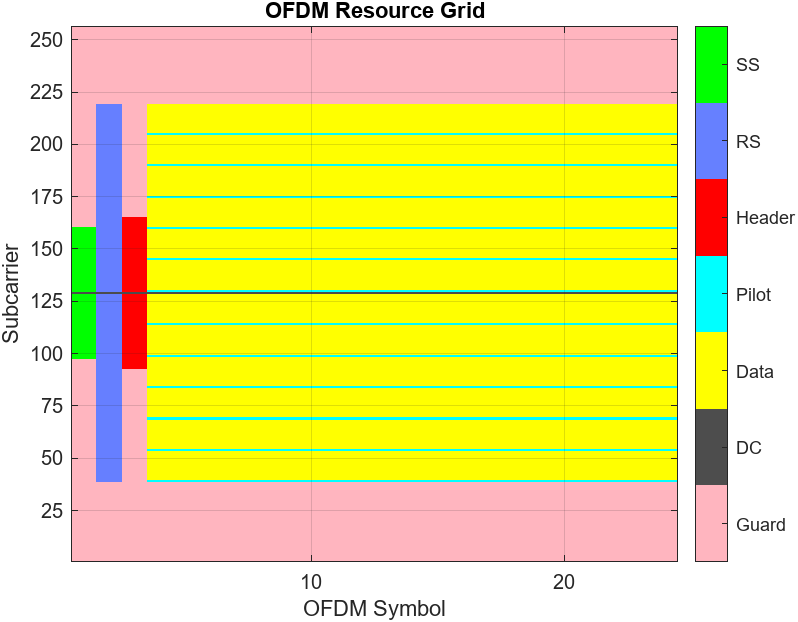

**Synchronization Symbol (SS)**

A synchronization (sync) signal is transmitted as the first symbol in the frame and consists of a 62-subcarrier signal centered at DC. This signal is designed to be bandwidth agnostic, meaning that all transmitters can transmit this signal regardless of the allocated bandwidth for that cell. The signal is meant to be detected by receivers to positively detect the cell signal and identify the frame boundary (the start of the frame).

**Reference Symbol (RS)**

A reference symbol is transmitted next. The reference symbol provides the receiver with a known reference to measure the channel distortion between the transmitter and receiver. The receiver processing can compensate for that distortion to recover the original signal as much as possible.

**Header Symbol**

The header conveys the bandwidth, subcarrier modulation scheme, and code rate of the OFDM data symbols to the receiver so that the receiver can properly decode the remainder of the frame. The information is important enough that it is transmitted with large signaling and coding margins to maximize correct decoding. Therefore, the symbol is coded at 1/2 rate with wide interleaving and modulated using BPSK. Since the channel distortion may change over time, the header symbol is transmitted immediately after the reference symbol to maximize the probability of correct reception. Because the bandwidth is not yet known, the header is always transmitted with a 72-subcarrier signal centered at DC.

**Pilot Signals**

Finally, to combat phase jitter seen at higher transmission frequencies, a pilot is transmitted at fixed subcarrier intervals within the data symbols to provide a phase reference to the receiver.

**DC and Guard Subcarriers**

Null subcarriers at the edge of the transmission spectrum are used to constrain spectral energy to a specified bandwidth. The subcarrier at DC is also nulled to keep the signal energy to within the linear range of the power amplifier.

**Transmitter Architecture**

The transmitter generates both control signals (sync, reference, header, and pilots) and data signals (transport block). The sync, reference, and header symbols are generated separately and time-multiplexed with the data symbols.

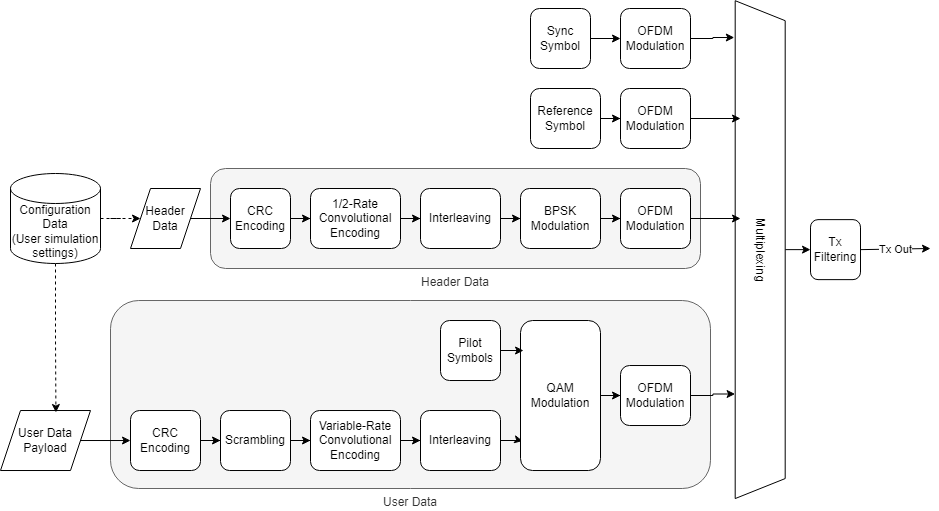

The data symbols comprise a single user populating a single transport block of data transmitted once per frame. A `comm.CRCGenerator` object computes the CRC for the transport block payload and appends it to the payload. The data is additively scrambled using a `comm.PNSequence` object to distribute the data power evenly across the transmission spectrum.  Interleaving is done with the `reshape` function to resist burst errors caused by deep fades. Convolutional encoding adds redundant bits for forward error correction and is done with the `convenc` function. Puncturing of the data increases data throughput by reducing the number of redundant bits. The transport block is modulated using the `qammod` function and is ready for transmission in an OFDM frame. All signals are OFDM-modulated using the `ofdmmod` function. The signal is filtered to reduce out-of-band emissions using dsp.`FIRFilter`, with coefficients generated using the `firpmord` and `firpm` filter design functions.

            % Transmit data
            [txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

## Apply Channel and Hardware Impairments

Introduce impairments to corrupt the transmitted signal, including fading, additive white Gaussian noise (AWGN), and carrier frequency offset. The impulse response of the channel is optionally shown to visualize potential inter-symbol interference leaking out of the cyclic prefix region of the OFDM symbol.

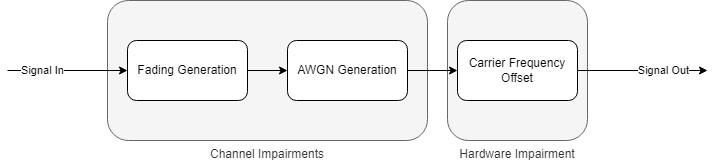

**Fading**

The CDL model is the responsible for modelling the fading of the system. Because the Doppler frequency is a function of transmission frequency, the normalized Doppler parameter is used to convey the Doppler frequency and more easily show the impact of mobile speed independent of the carrier frequency.

**Additive Noise**

The `awgn` function is used to apply AWGN to the faded signal. The input power into the awgn function is calculated as a function of per-subcarrier constellation power and number of occupied subcarriers. This input power is passed to the awgn function, along with the target SNR, to get the desired signal SNR.

**Carrier Frequency Offset**

Finally, the frequency offset is applied within the channel block. By using the `comm.PhaseFrequencyOffset` function to rotate the time-domain signal by the desired frequency.

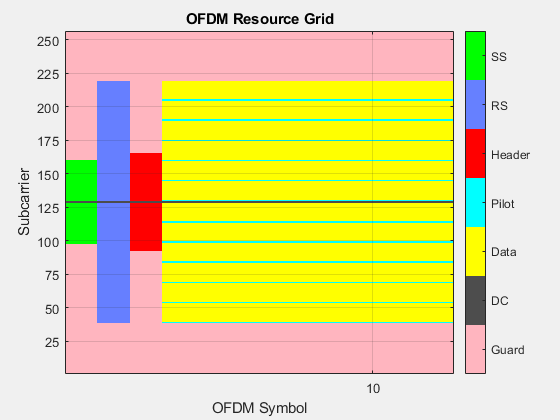

            % Process one frame of samples through channel
            [chanOut,pathGains,pathFilters,sampleTimes,sysParam] = helperOFDMChannel(txOut,chanParam,sysParam,frameNum,antennaParam,userParam);

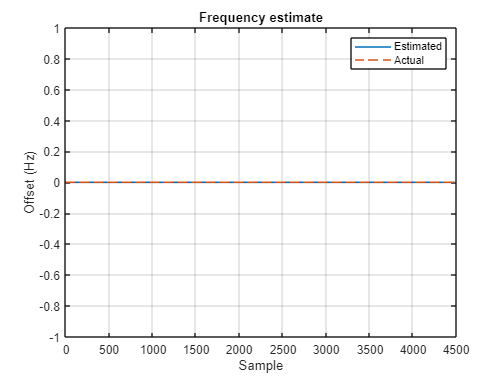

         
            % Save pathGains and pathFilters
            if simLoopIdx == 1
                if aux == false
                    aux = true;
                    complete_pathGains = pathGains;
                    complete_pathFilters = pathFilters;
                else
                    complete_pathGains = cat(3, complete_pathGains, pathGains);
                    complete_pathFilters = cat(3, complete_pathFilters, pathFilters);
                end

            end

## Channel Visualization

Use the `spectrumAnalyzer` function to visualize the received spectrum after fading and noise are added to the transmitted signal. As the simulation runs, you can see how the received signal constellation is negatively affected by the spectral nulls caused by multipath fading.

            if userParam.enableScopes    
                sa(txOut,chanOut);
            end

## Receiver Processing

The receiver reverses the transmitter processing. It also must detect and correct distortions caused by asynchronous timing, frequency offset, noise, time-varying fading, frequency-selective fading, and phase jitter.

The signal is lowpass filtered to remove out-of-band energy that could introduce noise. At the start of the receiver simulation, sync signal detection is performed by time-domain correlation and thresholding to determine the start of the frame. Until the sync symbol is detected, the receiver is not "camped" to any base station.

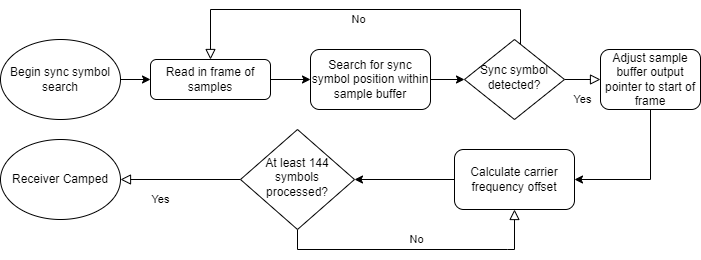

Following successful sync detection, 144 symbols are used by the automatic frequency correction (AFC) to estimate the frequency offset by detecting the phase shift between the cyclic prefix (a copy of the end of the symbol's samples that is transmitted at the beginning of an OFDM symbol) and the end of the symbol. Six symbols are used to obtain one frequency offset estimate, and the last 24 estimates are averaged to obtain the final filtered CFO estimate. Combined with knowledge of the duration of an OFDM symbol, the frequency offset can be estimated using inner product calculation. The frequency offset is then corrected with a numerically controlled oscillator using the `comm.PhaseFrequencyOffset` object. Once the signal is stable with respect to the timing offset and frequency offset, the receiver is considered camped and connected, and a complete frame is demodulated into OFDM subcarriers using `ofdmdemod`.

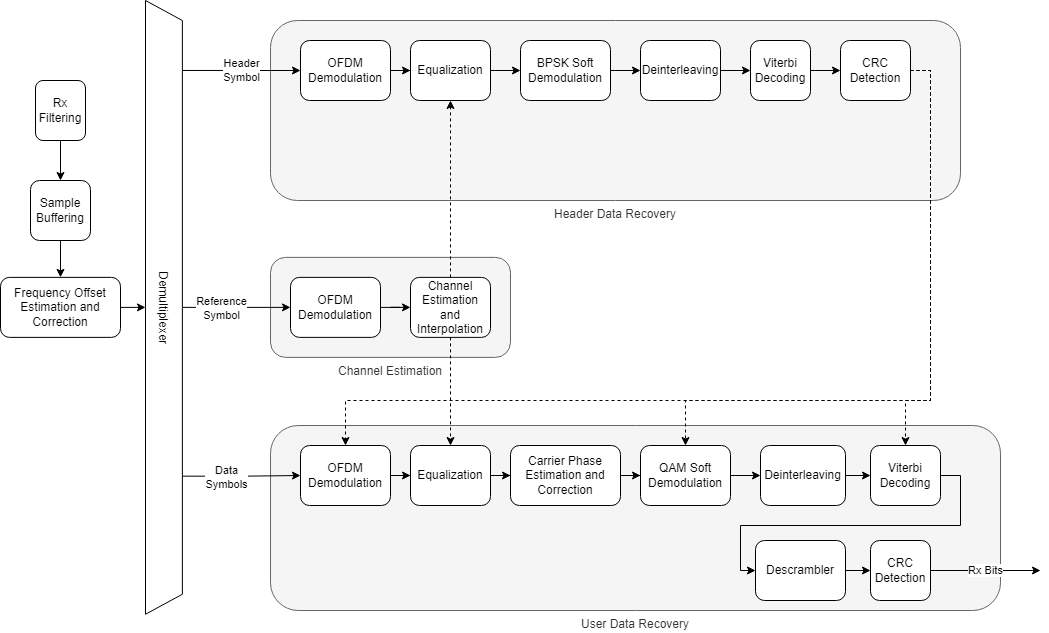

To combat time-varying fading, two reference symbols from adjacent frames are used to estimate the channel at different points in time, and then the channel estimates in between the two reference symbols are linearly interpolated to provide the channel estimates for the header and data symbols. The symbols are then equalized using the channel estimates with `ofdmEqualize`.

The header is extracted and decoded to obtain the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The data symbols are then demodulated according to the header parameters.

The pilots within the data symbols are used to estimate the common phase error (CPE) typically caused by phase jitter in mmWave transmissions. CPE affects all subcarriers equally. The error is derotated to remove the CPE from the data symbols, and the data subcarriers are soft-decoded into log-likelihood ratios (LLRs) using the `qamdemod` function.

Once the bitstream is available, the bits are deinterleaved before maximum-likelihood decoding is performed using the `vitdec` function which implements the Viterbi algorithm. The bits are then descrambled, and the `comm.CRCDetector` object computes the CRC and compares it with the appended CRC within the payload for transport block verification.

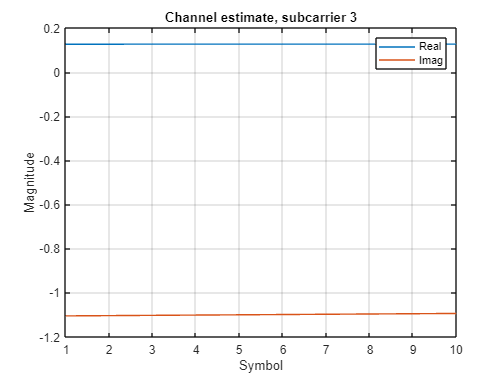

            % Run the receiver front-end
            rxIn = helperOFDMRxFrontEnd(chanOut,sysParam,rxObj);
        

            % Run the receiver processing
            [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);

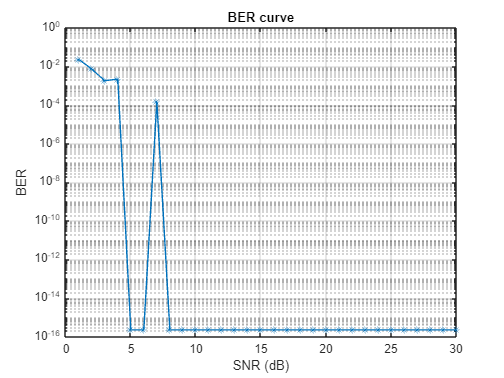

            sysParam.timingAdvance = toff;

            % Collect bit and frame error statistics
            if isConnected    
                % Continuously update the bit error rate using the |comm.ErrorRate|
                % system object
                BER = errorRate(...
                    sysParam.txDataBits(end-(2*sysParam.trBlkSize)+(1:sysParam.trBlkSize)), ...
                    rxDataBits);


                if aux_fft == 0
                    aux_fft = 1;
                    aux_channel = rxDiagnostics.estChannel;
                    aux_pathGains = pathGains;
                    aux_pathFilters = pathFilters;  
                end
            end

## Receiver Performance Visualization

Use the `comm.ConstellationDiagram` object to display the header constellation and data constellation in one plot. By varying the channel impairments, you can visualize the noise after receiver impairment compensation for all subcarriers superimposed on the plot. EVM and MER can be measured with respect to the reference constellation for each data modulation.

Channel impulse response for frame 1/101

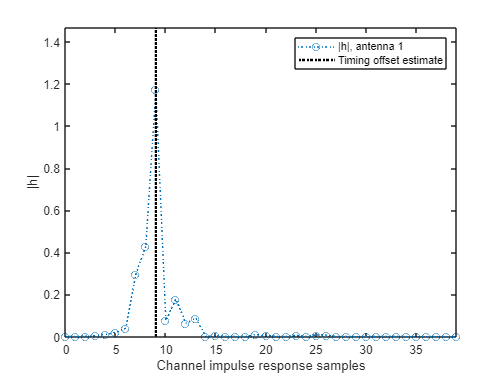

Channel impulse response for frame 2/101

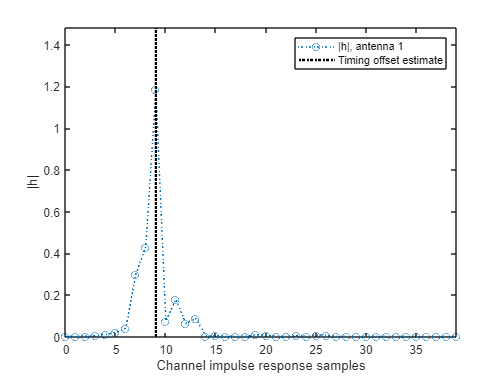

Channel impulse response for frame 3/101

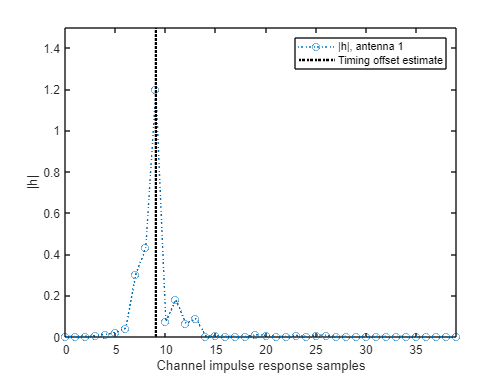

Channel impulse response for frame 4/101

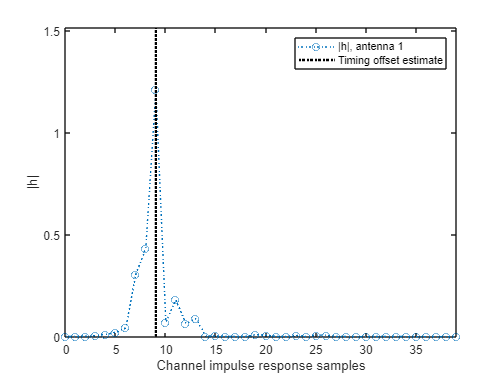

Channel impulse response for frame 5/101

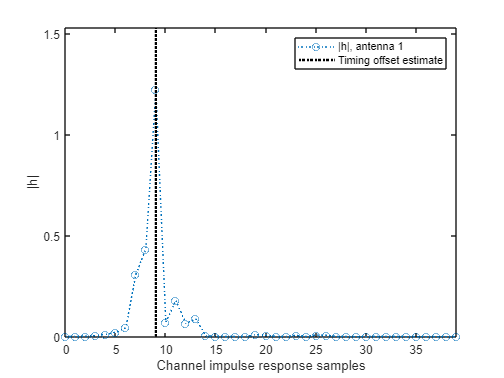

Channel impulse response for frame 6/101

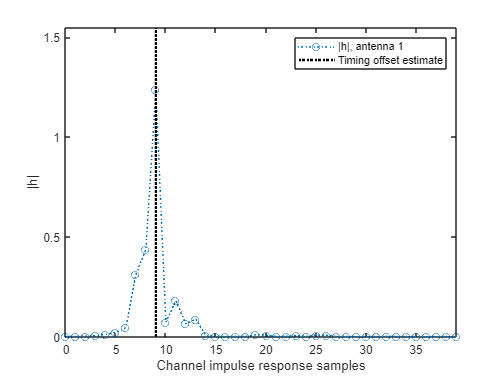

Channel impulse response for frame 7/101

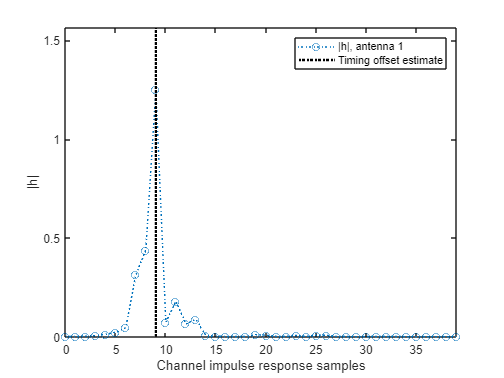

Channel impulse response for frame 8/101

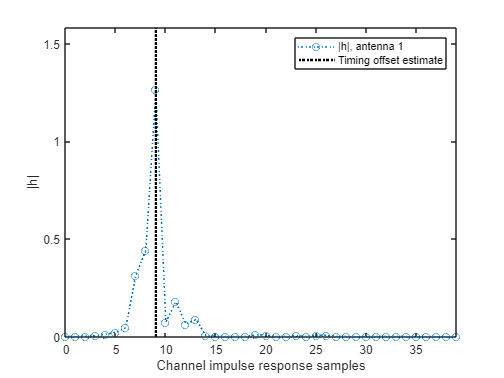

Channel impulse response for frame 9/101

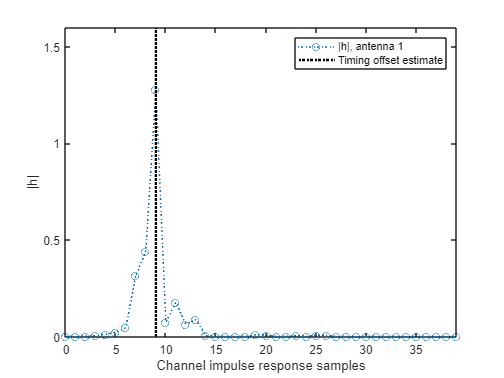

Channel impulse response for frame 10/101

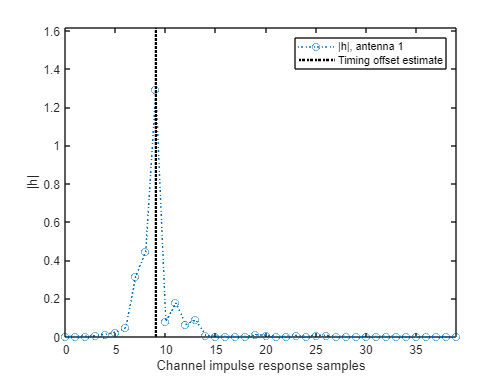

            if isConnected && userParam.enableScopes
                constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                        complex(rxDiagnostics.rxConstellationData(:)));
                if userParam.print_allData == 1
                    constDiag_noEq(complex(rxDiagnostics.rxConstellationHeader_NoEq(:)), ...
                            complex(rxDiagnostics.rxConstellationData_NoEq(:)));
                    constDiag_phase(complex(rxDiagnostics.rxConstellationData(:)), ...
                        complex(rxDiagnostics.rxConstellationData_NoPhaseCorr(:)));
                end
            end

        end % frame loop

## Clear Simulation and Compute Statistics

Following frame processing, clear out state information stored in persistent variables with the `clear` command. Accumulated bit error rate and frame error rate statistics are calculated and displayed at the simulated SNR. The simulation loads the next SNR and executes another run.

Channel Path for frame 1/101

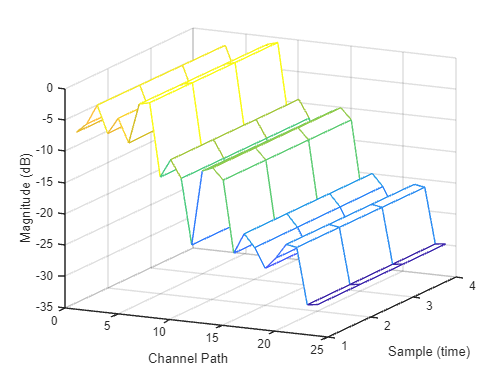

Channel Path for frame 2/101

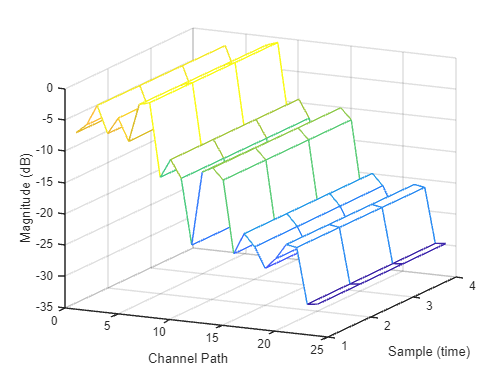

Channel Path for frame 3/101

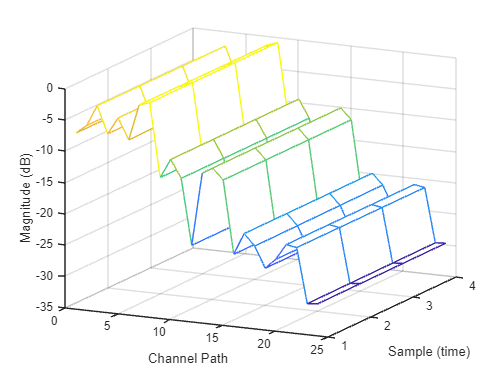

Channel Path for frame 4/101

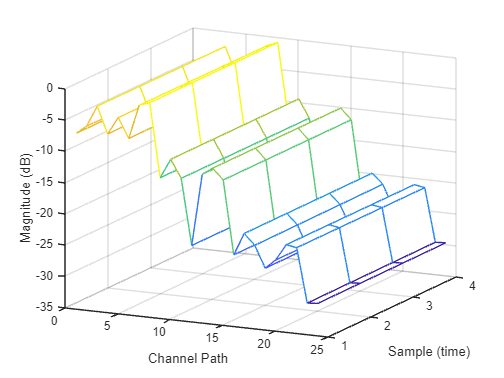

Channel Path for frame 5/101

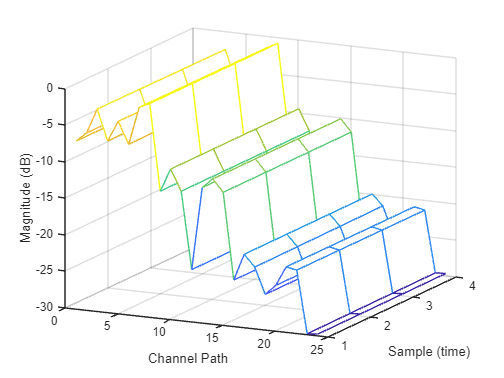

Channel Path for frame 6/101

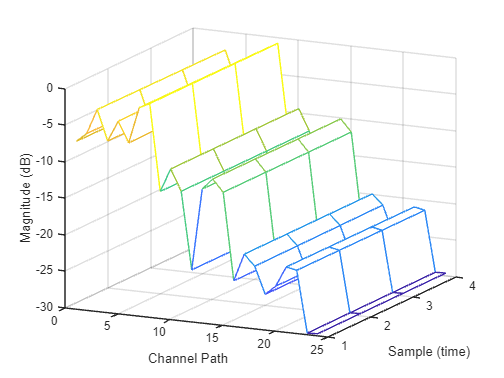

Channel Path for frame 7/101

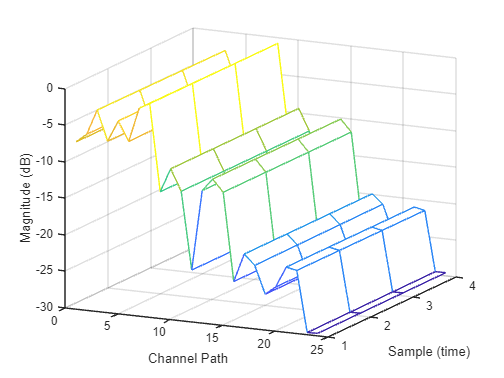

Channel Path for frame 8/101

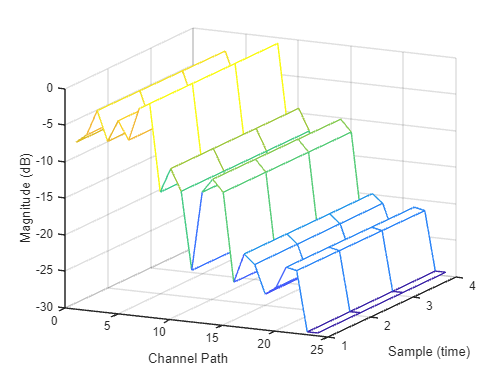

Channel Path for frame 9/101

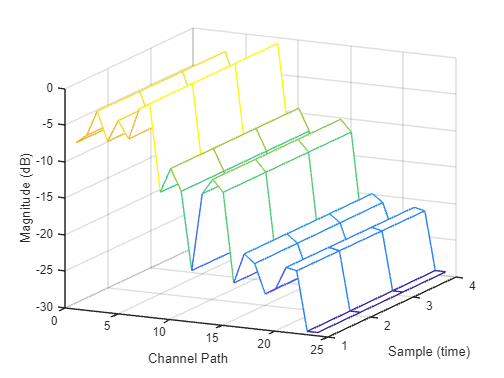

Channel Path for frame 10/101

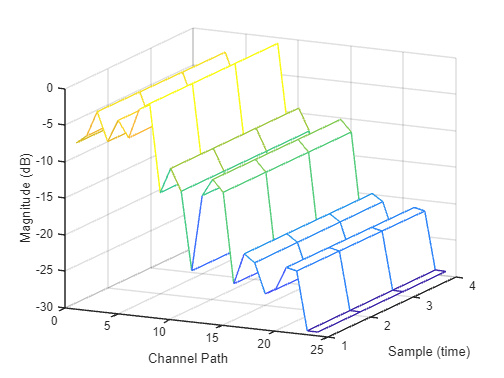

        % Clear out the |persistent| variables for the sync detection flag and
        % camped flag
        clear helperOFDMRx;
        clear helperOFDMRxSearch;

        % Compute data diagnostics
        if isConnected
            FER = sum(rxDiagnostics.dataCRCErrorFlag) / length(rxDiagnostics.dataCRCErrorFlag);
            fprintf('Simulation completed at %.2f SNR: BER = %d, FER = %d\n',SNRdB(simLoopIdx),BER(1),FER);
            BERResults(simLoopIdx) = BER(1);
            if (BER(1) == 0 && endSimBER0 == 1)
                % Crear un objeto COM para interactuar con el sistema operativo Windows
                shell = actxserver('WScript.Shell');

                % Configurar el título y el mensaje de la notificación
                titulo = 'Simulation completed';
                num = SNRdB(simLoopIdx);
                mensaje = num2str(num);

                % Mostrar la notificación
                shell.Popup(mensaje, 5, titulo, 64);
                
                % Liberar el objeto COM
                release(shell);

                return;
            end
        else

            fprintf('Simulation completed at %.2f SNR: Base station not detected.\n',SNRdB(simLoopIdx));
            fprintf('\n');
            BERResults(simLoopIdx) = 0.5; % default to high BER for plotting purposes
        end

        % Release object to reconfigure for the next simulation run
        release(errorRate);
    
    % SNR loop end
    end
end

# **Estimation with ofdmChannelResponse CODE**

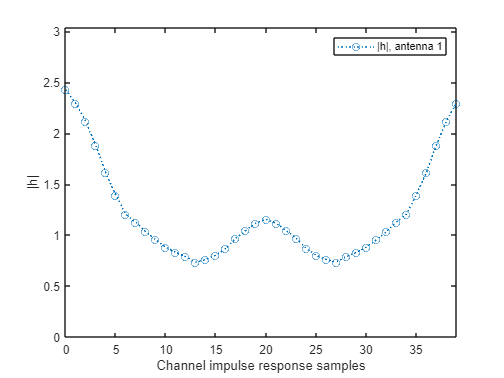

if strcmp(antennaParam.antennaSystem,"est_ofdmChannelResponse")== true 
    for simLoopIdx = 1:length(SNRdB)
        % Configure the channel
        chanParam = struct( ...
            'SNR',       SNRdB(simLoopIdx), ...
            'foff',      foff, ...       % normalized frequency offset (ppm)
            'doppler',   fmax*T, ...     % normalized Doppler frequency
            'model',     channelModelParam.model, ...
            'cdl', cdl_channelModel);


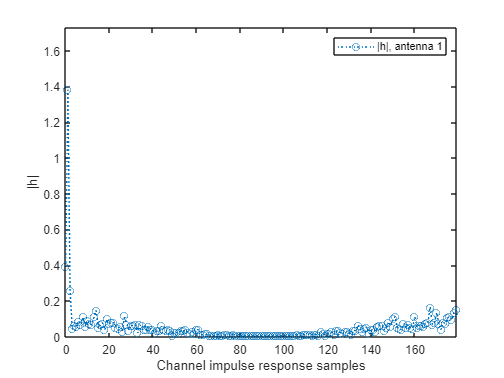

        fprintf('Configuring the fading AWGN channel at %d dB SNR and %d kph...\n', SNRdB(simLoopIdx), v_ue);
   
        sysParam.txDataBits = []; % clear tx data buffer

        sysParam.timingAdvance = (sysParam.FFTLen + sysParam.CPLen) * ...
            sysParam.numSymPerFrame; % set sample buffer timing advance
    
        % Instantiate an ErrorRate object to cumulatively track BER
        errorRate = comm.ErrorRate();

        fprintf('Transmitting %d frames with transport block size of %d bits per frame...\n', ...
            sysParam.numFrames,sysParam.trBlkSize);
        fprintf('Searching for synchronization symbol...');

        % Loop through all frames. Generate one extra frame to obtain the
        % reference symbol for channel estimates of the last frame.
        count = 0;
        error_count = 0;
        for frameNum = 1:sysParam.numFrames+1
            sysParam.frameNum = frameNum;
            % Generate random data to transmit. Replace with user data if desired.
            txParam.txDataBits  = randi([0 1],sysParam.trBlkSize,1);

            % Store data bits for BER calculations
            sysParam.txDataBits = [sysParam.txDataBits; txParam.txDataBits];
            sysParam.txDataBits = sysParam.txDataBits(max(1,end-2*sysParam.trBlkSize):end);


            % Transmit data
            [txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

            % Process one frame of samples through channel
            [chanOut,pathGains,pathFilters,sampleTimes,sysParam] = helperOFDMChannel(txOut,chanParam,sysParam,frameNum,antennaParam,userParam);
            

            % Save pathGains and pathFilters
            if simLoopIdx == 1
                if aux == false
                    aux = true;
                    complete_pathGains = pathGains;
                    complete_pathFilters = pathFilters;
                else
                    complete_pathGains = cat(3, complete_pathGains, pathGains);
                    complete_pathFilters = cat(3, complete_pathFilters, pathFilters);
                end
            end
            
            if userParam.enableScopes    
                sa(txOut,chanOut);
            end

            % Run the receiver front-end
            rxIn = helperOFDMRxFrontEnd(chanOut,sysParam,rxObj);
        

            % Run the receiver processing            
            [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRxEstReal(rxIn,sysParam,rxObj,pathGains,pathFilters,sampleTimes,txDiagnostics);

            sysParam.timingAdvance = toff;

            % Collect bit and frame error statistics
            if isConnected    
                % Continuously update the bit error rate using the |comm.ErrorRate|
                % system object
                BER = errorRate(...
                    sysParam.txDataBits(end-(2*sysParam.trBlkSize)+(1:sysParam.trBlkSize)), ...
                    rxDataBits);

                if aux_fft == 0
                    aux_fft = 1;
                    aux_channel = rxDiagnostics.estChannel;
                    aux_pathGains = pathGains;
                    aux_pathFilters = pathFilters;  
                end
            end            

            if isConnected && userParam.enableScopes
                constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                        complex(rxDiagnostics.rxConstellationData(:)));
                if userParam.print_allData == 1
                    constDiag_noEq(complex(rxDiagnostics.rxConstellationHeader_NoEq(:)), ...
                        complex(rxDiagnostics.rxConstellationData_NoEq(:)));
                    constDiag_phase(complex(rxDiagnostics.rxConstellationData(:)), ...
                        complex(rxDiagnostics.rxConstellationData_NoPhaseCorr(:)));
                end
            end
        end % frame loop

        % Clear out the |persistent| variables for the sync detection flag and
        % camped flag
        clear helperOFDMRxEstReal;
        clear helperOFDMRxSearch;

        % Compute data diagnostics
        if isConnected
            
            FER = sum(rxDiagnostics.dataCRCErrorFlag) / length(rxDiagnostics.dataCRCErrorFlag);
            fprintf('Simulation completed at %.2f SNR: BER = %d, FER = %d\n',SNRdB(simLoopIdx),BER(1),FER);
            BERResults(simLoopIdx) = BER(1);
            if (BER(1) == 0 && endSimBER0 == 1)
                % Crear un objeto COM para interactuar con el sistema operativo Windows
                shell = actxserver('WScript.Shell');

                % Configurar el título y el mensaje de la notificación
                titulo = 'Simulation completed';
                num = SNRdB(simLoopIdx);
                mensaje = num2str(num);

                % Mostrar la notificación
                shell.Popup(mensaje, 5, titulo, 64);
                
                % Liberar el objeto COM
                release(shell);

                return;
            end
        else
            fprintf('Simulation completed at %.2f SNR: Base station not detected.\n',SNRdB(simLoopIdx));
            fprintf('\n');
            BERResults(simLoopIdx) = 0.5; % default to high BER for plotting purposes
        end
        % Release object to reconfigure for the next simulation run
        release(errorRate);

        
    % SNR loop end
    end
end

## Diagnostics

A diagnostic structure captures various parameters for analysis during the simulation. Receiver performance can be recorded and plotted, such as the last frame's frequency offset tracking and channel estimation tracking. Error metrics like BER and FER/BLER can also be calculated and displayed.

% Plot the transmission grid
helperOFDMPlotResourceGrid(txGrid,sysParam);

% Plot the frequency offset estimator output
figure;
plot(rxDiagnostics.estCFO*sysParam.scs);
hold on;
plot(foff*fsamp*ones(length(rxDiagnostics.estCFO),1)/1e6,'--');
title('Frequency estimate');
xlabel('Sample');
ylabel('Offset (Hz)');
grid on;
legend('Estimated','Actual');

% Plot the channel estimate for one subcarrier
figure;
plot(real(rxDiagnostics.estChannel(3,:)));
hold on;
plot(imag(rxDiagnostics.estChannel(3,:)));
title('Channel estimate, subcarrier 3');
xlabel('Symbol');
ylabel('Magnitude');
grid on;
legend('Real','Imag');

% Plot a BER curve if more than one SNR was specified
if length(SNRdB) > 1
    figure;
    semilogy(SNRdB,BERResults+eps,'-*'); % add eps if no errors found
    title('BER curve');
    xlabel('SNR (dB)');
    ylabel('BER');
    grid on;
end

## Channel Impulse Response Display

%% Channel Impulse Response 
% https://es.mathworks.com/help/5g/ug/reconstruct-channel-impulse-response-using-cdl-channel-path-filters.html
%for i = 1:sysParam.numFrames+1
index = 0;
index_plot = 1;
for i = (10*index)+1:10*(index+1)
    % Genera la imagen (reemplaza esto con tu lógica para generar la imagen)
    [offset,mag] = nrPerfectTimingEstimate(complete_pathGains(:,:,i+1),complete_pathFilters(:,:,i+1));
    % Plot the magnitude of the channel impulse response.
    [Nh,Nr] = size(mag);
    fprintf('Channel impulse response for frame %d/%d',i,sysParam.numFrames+1)
    figure
    plot(0:(Nh-1),mag,'o:');
    hold on;
    plot([offset offset],[0 max(mag(:))*1.25*(index_plot+1)],'k:','LineWidth',2);
    axis([0 Nh-1 0 max(mag(:))*1.25]);
    legends = "|h|, antenna " + num2cell(1:Nr);
    legend([legends "Timing offset estimate"]);
    ylabel('|h|');
    xlabel('Channel impulse response samples');
    hold off
end

## Channel Paths Display

index_2 = 0;

for i = (10*index_2)+1:10*(index_2+1)
    if ((strcmp(sysParam.chanVisual,"All")) || (strcmp(sysParam.chanVisual,"Path Gains"))) 
        if size(complete_pathGains,1) == 1
            pathGains = complete_pathGains(:,:,i);
            pathGains = repmat(pathGains, 2, 1);
            fprintf('Channel Path for frame %d/%d',i,sysParam.numFrames+1)
            figure
            mesh(10*log10(abs(pathGains(:,:,1,1))));
            view(26,17); 
            xlabel('Channel Path');
            ylabel('Sample (time)'); 
            zlabel('Magnitude (dB)');
        else
            fprintf('Channel Path for frame %d/%d',i,sysParam.numFrames+1)
            figure
            pathGains = complete_pathGains(:,:,i);
            mesh(10*log10(abs(pathGains(:,:,1,1))));
            view(26,17);
            xlabel('Channel Path');
            ylabel('Sample (time)'); 
            zlabel('Magnitude (dB)');
        end
    end
end

Extra

Nh_control = 180;
aux_channel_fft = fft(aux_channel,Nh_control)/180;

%aux_channel_fft = fft(aux_channel,Nh)/(size(aux_channel_fft_complete,1)/Nh);

% Genera la imagen (reemplaza esto con tu lógica para generar la imagen)
[offset,mag] = nrPerfectTimingEstimate(aux_pathGains(:,:),aux_pathFilters(:,:));
% Plot the magnitude of the channel impulse response.
[Nh,Nr] = size(mag);
aux_mag = abs(fft(mag));

figure
plot(0:(Nh-1),aux_mag,'o:');
axis([0 Nh-1 0 max(aux_mag(:))*1.25]);
legends = "|h|, antenna " + num2cell(1:Nr);
legend([legends]);
ylabel('|h|');
xlabel('Channel impulse response samples');
hold off
% Genera la imagen (reemplaza esto con tu lógica para generar la imagen)

Nh = Nh_control;

figure
plot(0:(Nh-1),max(abs(aux_channel_fft(:,:)')),'o:');
%plot(0:(Nh-1),abs(aux_channel_fft),'o:');
axis([0 Nh-1 0 max(abs(aux_channel_fft(:)))*1.25]);
legends = "|h|, antenna " + num2cell(1:Nr);
legend([legends]);
ylabel('|h|');
xlabel('Channel impulse response samples');
hold off

## Summary

This example utilizes several MATLAB System objects and functions to perform DSP and digital communications operations common within an OFDM transmission system. Various scopes and plots help visualize the signal in both time and frequency domains to evaluate receiver performance.

## Appendix

The following helper functions are used in this example:

Setup:

- [helperOFDMTxInit.m](matlab:open('./helperOFDMTxInit.m'))

- [helperOFDMRxInit.m](matlab:open('./helperOFDMRxInit.m'))

- [helperOFDMSetParameters.m](matlab:open('./helperOFDMSetParameters.m'))

Common tx/rx helpers:

- [helperOFDMGetTables.m](matlab:open('./helperOFDMGetTables.m'))

- [helperOFDMFrontEndFilter.m](matlab:open('./helperOFDMFrontEndFilter.m'))

Transmitter:

- [helperOFDMTx.m](matlab:open('./helperOFDMTx.m'))

Channel:

- [helperOFDMChannel.m](matlab:open('./helperOFDMChannel.m'))

Receiver:

- [helperOFDMRx.m](matlab:open('./helperOFDMRx.m'))

- [helperOFDMRxFrontEnd.m](matlab:open('./helperOFDMRxFrontEnd.m'))

- [helperOFDMRxSearch.m](matlab:open('./helperOFDMRxSearch.m'))

- [helperOFDMChannelEstimation.m](matlab:open('./helperOFDMChannelEstimation.m'))

- [helperOFDMFrameSync.m](matlab:open('./helperOFDMFrameSync.m'))

- [helperOFDMFrequencyOffset.m](matlab:open('./helperOFDMFrequencyOffset.m'))

Visualization:

- [helperOFDMPlotResourceGrid.m](matlab:open('./helperOFDMPlotResourceGrid.m'))

The following helper functions can be modified to generate custom signals:

- [helperOFDMPilotSignal.m](matlab:open('./helperOFDMPilotSignal.m'))

- [helperOFDMRefSignal.m](matlab:open('./helperOFDMRefSignal.m'))

- [helperOFDMSyncSignal.m](matlab:open('./helperOFDMSyncSignal.m'))

*Copyright 2022 The MathWorks, Inc.*